load parkingLotCostVal.mat costVal

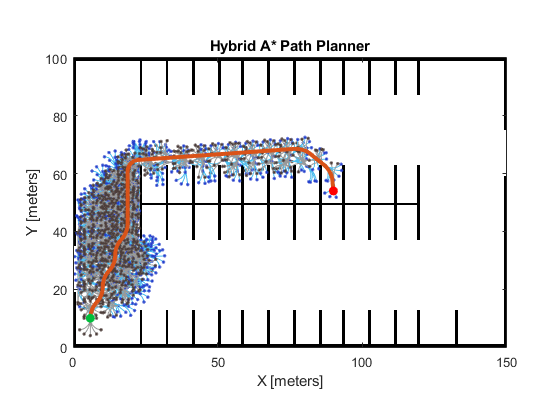

map = binaryOccupancyMap(costVal);
validator = validatorOccupancyMap;
validator.Map = map;
planner = plannerHybridAStar(validator,'MinTurningRadius',4,"MotionPrimitiveLength",6);
startPose = [6 10 pi/2];
%goalpose = [6 80 pi/2];
goalpose = [90 54 -pi/2];

refpath = plan(planner,startPose,goalpose);

p = refpath.States(:,[1:2]);

show(planner)

p1 = [0 -1 -2; 0 -1 -2]'

p1 =      0     0
    -1    -1
    -2    -2


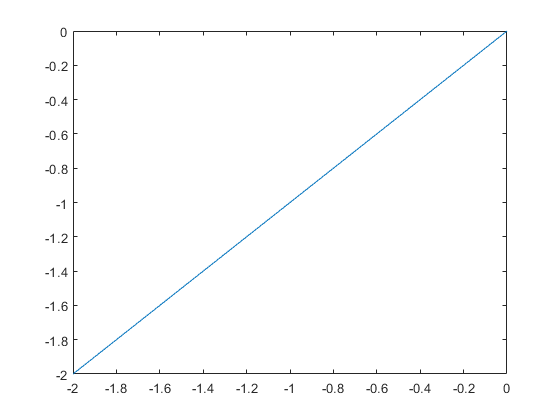

plot(p1(:,1),p1(:,2));

%p1(1,:);
p2 = [0 1 2 3 4 5 6 7; 0 0 0 0 0 0 0 0]';
p3 = [1 1 1 1 1 1 1 1 1 1 1 1 1 1; 1 1 1 1 1 1 1 1 1 1 1 1 1 1]';
p4 = zeros(5,2);

LigneDroite = [0 0 0 0; 0 -1 -2 -3]'

LigneDroite =      0     0
     0    -1
     0    -2
     0    -3


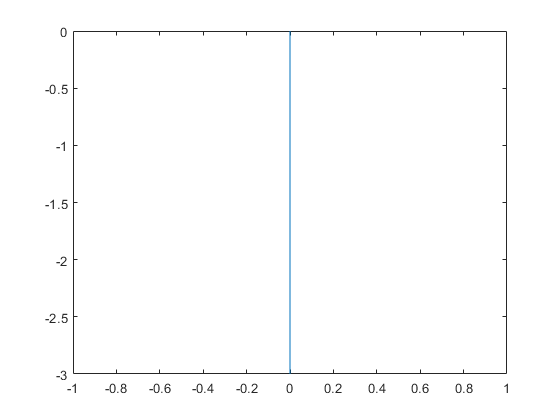

plot(LigneDroite(:,1),LigneDroite(:,2));

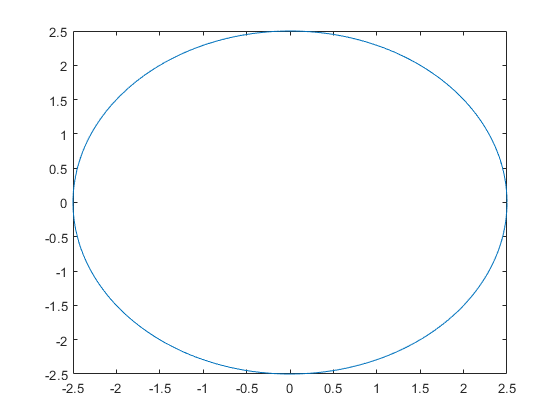

ang=0:0.01:2*pi; 
xp=2.5*cos(ang);
yp=2.5*sin(ang);
plot(xp,yp);

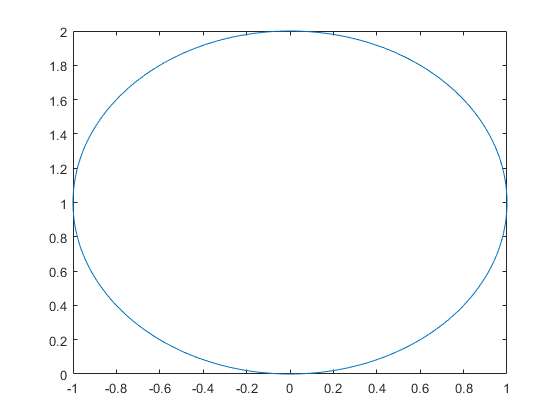


p5 = [0 xp;0 yp]';

ang=0:0.01:2*pi; 
xp6=1*cos(ang);
yp6=1*sin(ang);
plot(xp6,1+yp6);

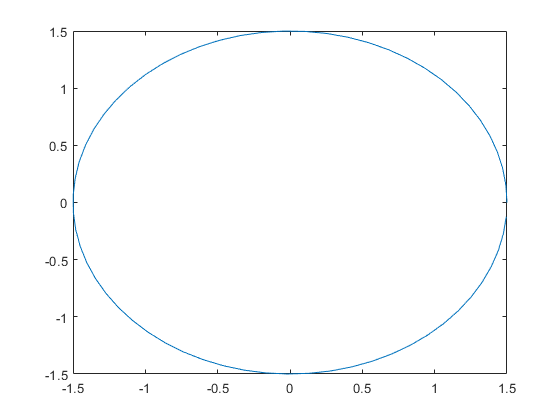


p6 = [0 xp6;0 1+yp6]';
%p6 = [p6;p6]; %deux cercles

ang=0:0.1:2*pi; 
xp7=1.5*cos(ang);

yp7=1.5*sin(ang);
plot(xp7,yp7);

p7 = [0 xp7;0 yp7]'

p7 =          0         0
    1.5000         0
    1.4925    0.1498
    1.4701    0.2980
    1.4330    0.4433
    1.3816    0.5841
    1.3164    0.7191
    1.2380    0.8470
    1.1473    0.9663
    1.0451    1.0760


%p6 = [p6;p6]; %deux cercles



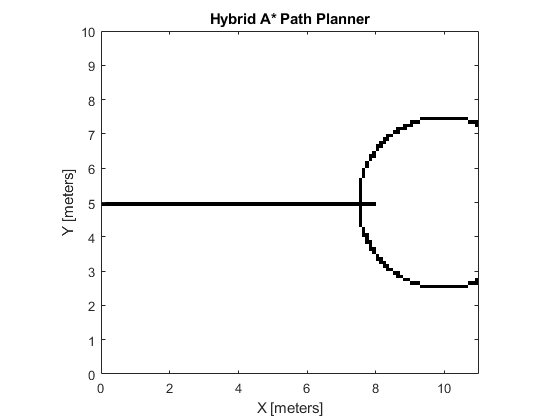

map = binaryOccupancyMap(11,10,10);
% setOccupancy(map,[5 5], 10);
x = [linspace(0,8) 10+xp]';
y = [linspace(5,5) 5+yp]';
setOccupancy(map,[x y],1000);

validator = validatorOccupancyMap;
validator.Map = map;
planner = plannerHybridAStar(validator);

figure
show(planner)

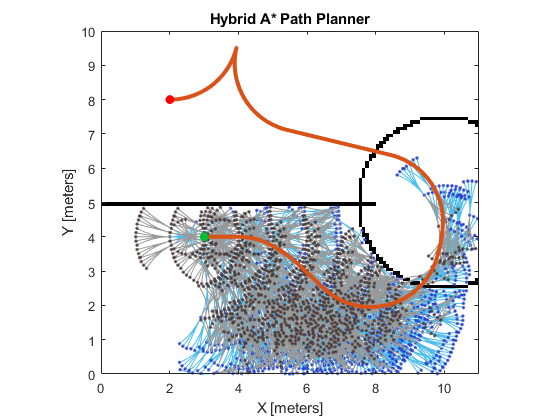

startPose = [3 4 0];
goalpose = [2 8 0];
refpath = plan(planner,startPose,goalpose);

p = refpath.States(:,[1:2]);

figure
show(planner)


p11 = p(:,1);
p22 = p(:,2);

ptest = [0 p11'; 0 p22']'

ptest =          0         0
    3.0000    4.0000
    4.0000    4.0000
    4.9589    3.7552
    5.7677    3.1716
    6.4994    2.4900
    7.3679    2.0155
    8.3575    2.0155
    9.2259    2.4900
    9.7606    3.3227




ptest2 = [0 1; 0 1]'

ptest2 =      0     0
     1     1


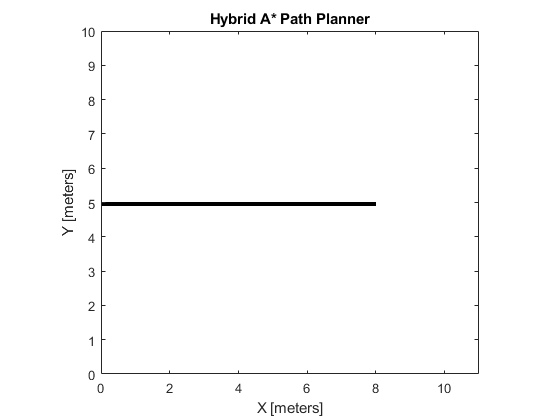

map = binaryOccupancyMap(11,10,10);
x = [linspace(0,8) ]';
y = [linspace(5,5) ]';
%plot(x,y)
setOccupancy(map,[x y],1000);

validator = validatorOccupancyMap;
validator.Map = map;
planner = plannerHybridAStar(validator);

figure
show(planner)


startPose = [6.5 4.5 0];
goalpose = [8.7 6 pi/2];
refpath = plan(planner,startPose,goalpose);

pA = refpath.States(:,[1:2]);
pA

pA =     6.5000    4.5000
    7.4896    4.6244
    8.3581    5.0988
    8.7000    6.0000


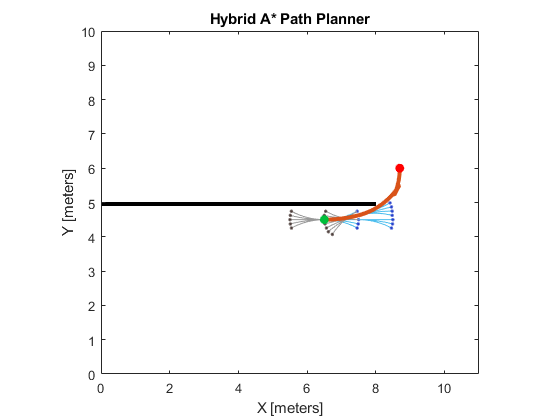

figure
show(planner)

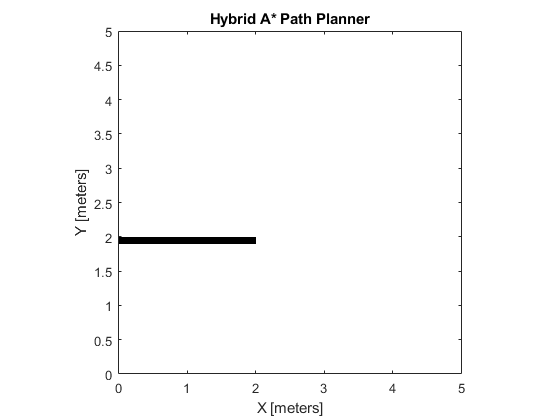

map = binaryOccupancyMap(5,5,10); %(longueur,largeur,cellules par metres)
x = [linspace(0,2) ]';
y = [linspace(2,2) ]';
%plot(x,y)
setOccupancy(map,[x y],1000);

validator = validatorOccupancyMap;
validator.Map = map;
planner = plannerHybridAStar(validator);

figure
show(planner)


startPose = [0 0 pi/2];
goalpose = [3 3 pi/2];
refpath = plan(planner,startPose,goalpose);

pB = refpath.States(:,[1:2]);
pB

pB =          0         0
    0.2448    0.9589
    0.9194    1.6829
    0.0779    1.1426
    0.9778    1.5727
    1.9368    1.8426
    2.7497    2.5802
    3.0000    3.0000


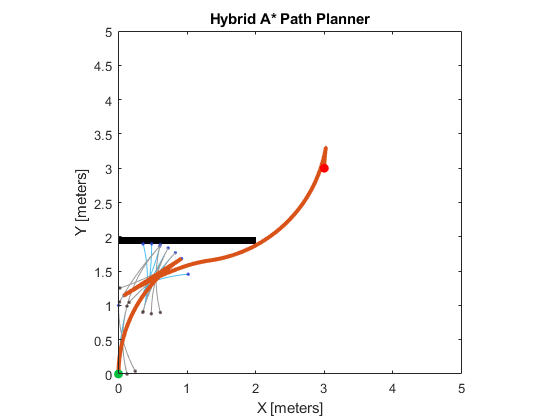

figure
show(planner)

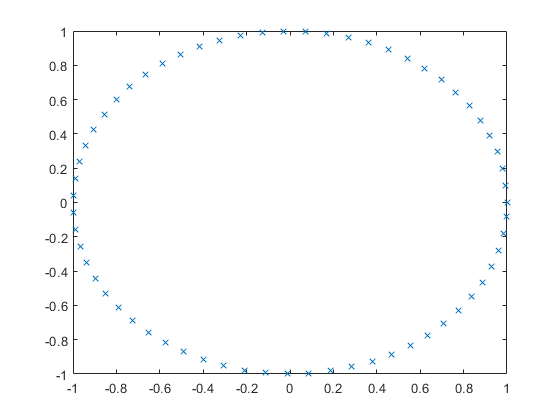

% cercle A star

ang=0:0.1:2*pi; 
xp6=1*cos(ang);
yp6=1*sin(ang);
plot(xp6,yp6,'x');

setOccupancy(maps,[xp6 yp6],1000);

MapTools Projections 

CLASS                 NAME                                ID STRING        
Cylindrical           Balthasart Cylindrical              balthsrt         
Cylindrical           Behrmann Cylindrical                behrmann         
Cylindrical           Bolshoi Sovietskii Atlas Mira*      bsam             
Cylindrical           Braun Perspective Cylindrical*      braun            
Cylindrical           Cassini Cylindrical-Standard        cassinistd       
Cylindrical           Cassini Cylindrical                 cassini          
Cylindrical           Central Cylindrical*                ccylin           
Cylindrical           Equal Area Cylindrical              eqacylin         
Cylindrical           Equidistant Cylindrical             eqdcylin         
Cylindrical           Gall Isographic                     giso             
Cylindrical           Gall Orthographic                   gortho           
Cylindrical           Gall Stereographic*                 gstereo

Check for incorrect argument data type or missing argument in call to function 'setOccupancy'.


validator = validatorOccupancyMap;
validator.Map = map;
planner = plannerHybridAStar(validator);

figure
show(planner)


freq = 2*pi/30;
Ts = 0.1; % Sampling time
t = 0:Ts:30; % Simulation time
xRef = 0 +1*sin(freq*t); 
yRef = 0 - 1*sin(2*freq*t);
plot(xRef,yRef,'x');
title('Butterfly Path Waypoints');

p8=[0 xRef;0 yRef]'
p8=[p8;p8]
p8=[p8;p8]

%lemniscate de bernouilli 
freq = 2*pi/30;
Ts = 0.033; % Sampling time
t = 0:Ts:30; % Simulation time
xRef = -2.1213+1.5*cos(freq.*t).*sqrt(2.*cos(2.*freq*t)); 
yRef = 0.6*sin(freq.*t).*sqrt(2.*cos(2.*freq*t));
%plot(real(xRef),real(yRef));


p8=[0 real(xRef);0 real(yRef)]'
p8=[p8;p8]
p8=[p8;p8]
plot(p8(:,1),p8(:,2))
title('lemniscate de Bernoulli');

%--------------------------------------------------------
% Courbe paramétrique
% d'aprés 'Apprendre et maitriser Matlab'
%---------------------------------------------------------

echo on;
%-------------------------------------------
%     lemniscate de Bernoulli
%        x = 2*t /(1+t^4)
%        y = (2*t^3)/(1+t^4) 
%---------------------------------------------
echo off;
t=-100:0.1:100; 	% domaine
x = (1*t)./(1+t.^4);        % ./ et .^ élément par élément
y = (1*t.^3)./(1+t.^4);
clf;
plot(x,y,'r');
xlabel('x');
ylabel('y');
title('lemniscate de Bernoulli');
grid;

p8=[x;y]'
p8=[p8;p8]

theta = linspace (-pi/4,pi/4);
x = 0.5.*cos(theta).*sqrt(2.*cos(2.*theta));
y = -1.*sin(theta).*sqrt(2.*cos(2.*theta));
plot(x,y,-x,-y), grid on, 
axis ('equal')

p81=[x;y]'
p82=[-x;-y]'
p8=[p81;p82]

circle(0,0,1.5)

function circle(x,y,r)
    %pas de 0.1 
    ang=0:0.1:2*pi; 
    xp=r*cos(ang);
    yp=r*sin(ang);
    plot(x+xp,y+yp,'x');
end